close all; clear; clc
DSM_constants;

%========= Calculs préliminaires ================

% masse totale du système

    m_r = (pi*D_r*D_r*L_r/4 - pi*D_i*D_i*(L_r-L_a)/4 - pi*D_a*D_a*L_a/4)*rho_r + (pi*D_a*D_a*L_a/4- pi*D_i*D_i*L_a/4)*rho_a; % masse totale

% masse des différents composants

    m_a = pi*(D_a*D_a - D_i*D_i)/4*L_a*rho_a; % masse aimant
    m_r1 = pi*(D_r*D_r - D_a*D_a)/4*L_a*rho_r; % masse autour aimant
    m_r2 = pi*(D_r*D_r - D_i*D_i)/4*(L_r - L_a) * rho_r; % reste de la masse

% position du centre de gravité
   
    z_CG = (m_a*L_a/2 + m_r1*L_a/2 + m_r2*(3*L_r/4))/m_r; % depuis le point le plus à gauche
    z_CGcentre = z_CG - L_r/2; % centre de masse sur z par rapport au centre
    y_CGcentre = 0; % centre de masse sur y par rapport au centre

% distance des supports et du balourd du CG

    z_support1CG = -(z_CG - z_sup1); % position du support 1 par rapport au CG
    z_support2CG = z_sup2 - z_CG; % position du support 2 par rapport au CG
    z_balourdCG = z_CGcentre + L_a/2; % position du balourd par rapport au CG

% Moment d'interties
    
    J_rz = pi/32*(rho_r*(L_r - L_a)*(D_r^4 - D_i^4) + rho_a*L_a*(D_a^4 - D_i^4) + rho_r*L_a*(D_r^4 - D_a^4)); % moment d'intertie z du rotor

    % formule pour un cylindre creux autour de leur centre de gravité: 
    % J_y = J_x = (1/12)*M*(3*R_i + 3*R_e + l^2)

    J_y2cg = (1/12)*m_r2*(3*(D_r/2)^2 + 3*(D_i/2)^2 + (L_r - L_a)^2);
    J_y1cg = (1/12)*m_r1*(3*(D_r/2)^2 + 3*(D_a/2)^2 + L_a^2);
    J_y3cg = (1/12)*m_a*(3*(D_a/2)^2 + 3*(D_i/2)^2 + L_a^2);
    
    % calcul des interties au CG du rotor

    J_y1 = J_y1cg + m_r1*(z_CG - L_a/2)^2;
    J_y2 = J_y2cg + m_r2*(L_a/2 + 0.5*L_r - z_CG)^2; 
    J_y3 = J_y3cg + m_a*(z_CG - L_a/2)^2;

    J_ry = J_y1 + J_y2 + J_y3; % Inertie totale du rotor autour de y


% Rigidités de la courroie

    k_c1 = E_c * h_c * t_c / l_c1;
    k_c2 = E_c * h_c * t_c / l_c2;
    k_c3 = E_c * h_c * t_c / l_c3;
    k_c4 = E_c * h_c * t_c / l_c4;
    k_c5 = E_c * h_c * t_c / l_c5;
    k_c6 = E_c * h_c * t_c / l_c6;
    k_c7 = E_c * h_c * t_c / l_c7;


% Inerties et rigidités des lames

    I_lx=t_l*(h_l^3)/12;
    I_lz=h_l*(t_l^3)/12;

    kl_x = 12*E_l*I_lz/L_l^3;
    kl_z = 12*E_l*I_lx/L_l^3;

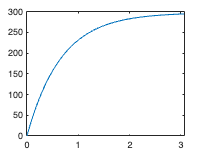

%========= Accélération du groupe d'entraînement ================

% Rapports de transmission

    % Rapport de transmission moteur-courroie

    i_mc = 1 / (D_m / 2);

    % Rapport de transmission courroie-poulie

    i_cp = D_p / 2;

    % Rapport de transmission moteur-poulie

    i_mp = i_mc * i_cp;
    % i_mp = D_p / D_m;

    % Rapport de transmission moteur-rotor

    i_mr = D_r / D_m;
    % i_mr2 = i_mc * D_r

% Vitesse stationnaire du moteur
    
    w_rs2 = w_rs * 2*pi/60;
    w_ms = w_rs2 * i_mr;%rad/s

% Moments d'inertie réduits
    
    % Moment d'inertie réduit moteur
    J_mz_red = J_mz;

    % Moment d'inertie réduit poulie
    J_pz_red = J_pz/(i_mp)^2;

    % Moment d'inertie réduit rotor
    J_rz_red = J_rz/(i_mr)^2;

% Couple résistant rotor

    b_r = T_resNulle;
    a_r = (T_resMax - b_r) / w_rs2;

% Couple résistant rotor réduit

    %Coeff. b couple rotor réduit
    b_r_red = T_resNulle/i_mr;

    %Coeff. a couple rotor réduit
    a_r_red = (T_resMax/i_mr - b_r_red)/w_ms;

%Moment d'inertie réduit du système entraînement (global)

    J_z_red = J_mz_red + 5*J_pz_red + J_rz_red;

%Couple moteur

    Tm = a_r_red*w_ms + b_r_red;

    %Coeff. b couple moteur
    b_m = Tm;

    %Coeff. a couple moteur
    a_m = 0;

    %Coeff. a couple système d'entraînement (globale)
    a_red = -a_r_red + a_m;

    %Coeff. b couple système d'entraînement (globale)(couple système
    %d'entraînement = couple moteur - couple rotot (résistant)
    b_red = -b_r_red + b_m;

% Temps de démaragge système d'entraînement

t_d_99 = J_z_red/a_red*log(0.99*a_red/b_red*w_ms+1);

%Courbe de d'accélération
t=linspace(0,t_d_99,100);

w_m = b_red/a_red*(exp(a_red/J_z_red*t)-1);

%accélération groupe d'entraînement
a_m = b_red/J_z_red*exp(a_red/J_z_red*t);
figure(1)
plot(t,w_m)

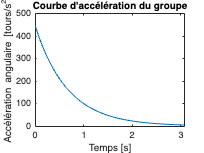

figure(2)
plot(t,a_m)
title("Courbe d'accélération du groupe")
xlabel('Temps [s]') 
ylabel('Accélération angulaire [tours/s^2]') 

%========= Analyse dynamique du groupe d'entraînement ================

% Rigidités courroie réduites
    
    k_c1_red = k_c1 / i_mc^2;
    k_c2_red = k_c2 / i_mc^2;
    k_c3_red = k_c3 / i_mc^2;
    k_c4_red = k_c4 / i_mc^2;
    k_c5_red = k_c5 / i_mc^2;
    k_c6_red = k_c6 / i_mc^2;
    k_c7_red = k_c7 / i_mc^2;

% Vitesse critique minimale

    % équations de mouvement des 7 masses
    % [M](d^2/dt^2)theta + [K]theta = Q*

    M = diag([J_mz_red J_rz_red J_pz_red J_pz_red J_pz_red J_pz_red J_pz_red]);
    %Raideur equivalente pour schéma du modèle dynamique réduit et simplifié
    K = [k_c1_red+k_c7_red, 0, -k_c1_red, 0, 0, 0, -k_c7_red
         0, k_c6_red+k_c5_red, 0,0, 0, -k_c5_red, -k_c6_red
         -k_c1_red, 0, k_c2_red+k_c1_red, -k_c2_red, 0, 0, 0
         0, 0, -k_c2_red, k_c3_red+k_c2_red, -k_c3_red, 0, 0
         0, 0, 0, -k_c3_red, k_c4_red+k_c3_red, -k_c4_red, 0
         0, -k_c5_red, 0, 0, -k_c4_red, k_c5_red+k_c4_red, 0
         -k_c7_red, -k_c6_red, 0, 0, 0, 0, k_c7_red+k_c6_red];
    
    N = (inv(M)*K);

    [V,D] = eig(N);

    diagonal = diag(D);
    sorted_diag = sort(diagonal);
    criticalFreq = sorted_diag(2);

    w_m0_min = sqrt(criticalFreq)/(2*pi)*60/i_mr;


    beta = w_rs/w_m0_min;


% Vitesse critique du modèle réduit simplifié

    K_equivalent1 = 1/(1/k_c1_red+1/k_c2_red+1/k_c3_red+1/k_c4_red+1/k_c5_red);
    K_equivalent2 = (k_c7_red*k_c6_red)/(k_c7_red+k_c6_red);
    K_c_tot_red = K_equivalent1+K_equivalent2;

    w0_simp = sqrt(K_c_tot_red*(1/J_mz_red+1/J_rz_red))/(2*pi)*60;

% Erreur relative sur la vitesse critique minimale

    erreur_w0 = (w0_simp/i_mr-w_m0_min)/w_m0_min;

%========= Réponse forcée du rotor ================

%Plage du balourd

    m_BalourdMin = D_r/2 * m_r *0.00001;
    m_BalourdMax = D_r/2 * m_r * 0.001;
    plageBalourd = [m_BalourdMin, m_BalourdMax];


% Calcul pour trouver m_s
    L_s1 = L_r/2 + z_CGcentre;
    L_s2 = L_r/2 - z_CGcentre;
    % Assumes all required constants are already defined:
    % m_r, J_rz_red, L_s1, L_s2, kl_x, d, plageBalourd, etendue_mesure
    
    d = z_CG - L_a/2; 
    
    
    ms = linspace(0.001, 0.1, 1000);         % ms sweep
    D = [1; d];
    
    for i = 1:length(ms)
        m_s = ms(i);
        isValid = true;  % Assume valid unless proven otherwise
        
        % Mass and stiffness matrices
        M = [(m_r + 2*m_s),            m_s*(L_s2 - L_s1);
             m_s*(L_s2 - L_s1),        J_rz + m_s*(L_s1^2 + L_s2^2)];
        
        K = [4*kl_x,                   2*kl_x*(L_s2 - L_s1);
             2*kl_x*(L_s2 - L_s1),     2*kl_x*(L_s1^2 + L_s2^2)];
        
        % Eigenvalue problem to get natural frequency
        eigenvalues = eig(M \ K);
        natural_frequencies = sqrt(eigenvalues);  % rad/s

        w_max = max(natural_frequencies);
        
        buffer = 0.01;  % 1% buffer
        omega = linspace(w_max * (1 + buffer), 1257, 1000);   % omega sweep
        
        for j = 1:length(omega)
            w = omega(j);
            
        
            invertedMatrix = (K - w^2 * M)\eye(2);
        
            % Compute accelerations for both min and max imbalance
            accelVect_min = w^4 * m_BalourdMin * (invertedMatrix * D);
            accelVect_max = w^4 * m_BalourdMax * (invertedMatrix * D);
        
            accel_x_min = accelVect_min(1);
            accel_theta_min = accelVect_min(2);
            accel_x_max = accelVect_max(1);
            accel_theta_max = accelVect_max(2);
        
            accel_x1_min = abs(accel_x_min - L_s1 * accel_theta_min);
            accel_x2_min = abs(accel_x_min + L_s2 * accel_theta_min);
            accel_x1_max = abs(accel_x_max - L_s1 * accel_theta_max);
            accel_x2_max = abs(accel_x_max + L_s2 * accel_theta_max);
        
            % If any acceleration is outside the measurement range, m_s is not valid
            if any([accel_x1_min, accel_x1_max, accel_x2_min, accel_x2_max] < etendue_mesure(1)) || ...
               any([accel_x1_min, accel_x1_max, accel_x2_min, accel_x2_max] > etendue_mesure(2))
               isValid = false;
                break;  % No need to check other ω
            end
         end

      if isValid
          fprintf('Minimal valid m_s for ALL ω: %.4f\n', m_s);
          break;
      end
   end

   %{ 
% Construct matrices again with valid m_s
    M = [(m_r + 2*m_s),            m_s*(L_s2 - L_s1);
         m_s*(L_s2 - L_s1),        J_rz_red + m_s*(L_s1^2 + L_s2^2)];
    
    K = [4*kl_x,                   2*kl_x*(L_s2 - L_s1);
         2*kl_x*(L_s2 - L_s1),     2*kl_x*(L_s1^2 + L_s2^2)];
    
    % Generalized eigenvalue problem: M⁻¹K
    M_invK = M \ K;
    
    % Compute eigenvalues and eigenvectors
    eigenvalues = eig(M_invK);
    
    % Compute natural angular frequencies
    natural_frequencies = 60/(2*pi)*sqrt(eigenvalues);
    
    % Display
    disp('Natural angular frequencies (RPM):');
    disp(natural_frequencies);
   %}
    
        
    

